# Synthetic Data FacTBRK experiments

addpath('../tproduct toolbox 2.0 (transform)/')
warning('off','all')

%To-do: implement trial averaging, try different inner block sizes, do
%experiment for all other combinations of system sizes

First, we'll generate a tensor linear system.

%fixed:
p = 7;
n = 5;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_2 = 10;

%V underdetermined (m_1 > m_2), A overdetermined (m >= 20)--Works
%m = 20;
%m = 30;
m = 40;
m_1 = 5;

%V underdetermined (m_1 > m_2), A underdetermined (m < 20)--Doesn't Works
%m = 10;
%m = 15;%
%m_1 = 5;

%V overdetermined (m_1 < m_2), A overdetermined (m > 20)--Doesn't work
% m = 20;
% m = 30;
%m = 40;
%m_1 = 12;

%generate tensors
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
A=tprod(U,V); 

X_true = randn(m_1,n,p);


%generate consistent measurements
B = tprod(A, X_true);


%generate equivalent matrix system
[matU,matV, matB,matX_true] = matricization_factorized(U,V,B,X_true);

Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(A),B);
X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
norm(X_LN(:)-X_LN2(:))

ans = 1.3081e-14

norm(X_LN(:)-X_true(:))

ans = 1.0649e-14

num_its = 100; %num iterations
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_size = 5; %remember that the updates only make sense for block size <= number of columns

errs = zeros(size(out_block_sizes,2),num_its+1);
res_errs = zeros(size(out_block_sizes,2),num_its+1);
ln_errs = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1);
norms = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs(i,:),res_errs(i,:),ln_errs(i,:),res_ln_errs(i,:),norms(i,:)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

Let's plot the errors.

%plot errors vs iterations
clc
figure(1);
hold on
line_styles = {'b-','r--','k-.','c:','g-*'};
for i = 1:size(out_block_sizes,2)
    i
    semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
end

i = 1

i = 2

i = 3

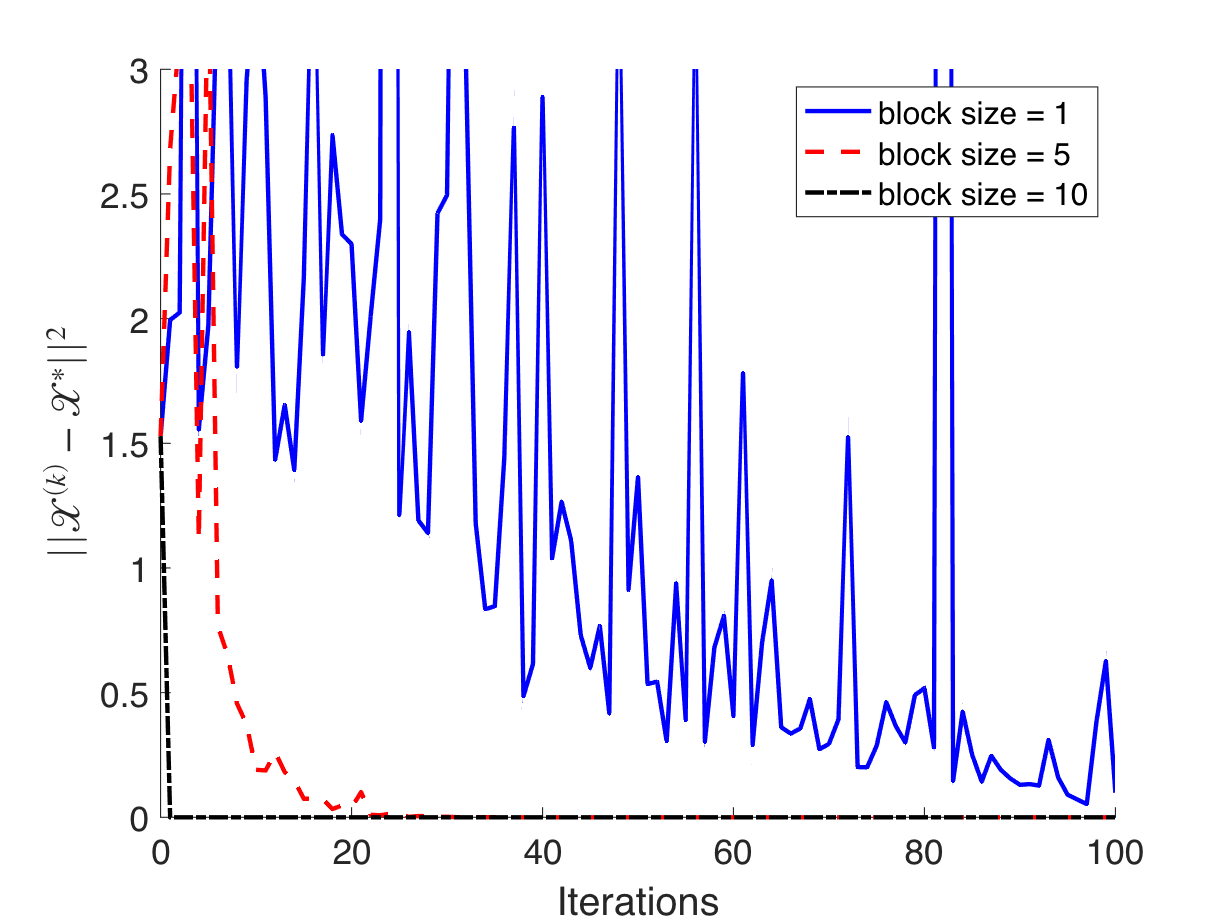

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
ylim([0,3])
legendStrings = "block size = " + string(out_block_sizes);
legend(legendStrings)
hold off


%saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");